% Sample random combinations of 3-segment arms, and see how their
% workspaces compare.

% Sample arm designs with varying outer radii
rho_range = [0.02, 0.08];
N_segs = 5;
N_arms = 50;

rng(20);
mat_rhos = rand(N_segs, N_arms) * (rho_range(2) - rho_range(1)) + mean(rho_range)/2;

% Hold the inner radii constant at 0.01
rho_inner = 0.01 * ones(N_segs, 1);

l_0 = 0.5;

arms = ArmSeries.empty(N_arms, 0);
for i = 1 : size(mat_rhos, 2)
    rho_outer_i = mat_rhos(:, i);
    arms(i) = ArmSeriesFactory.varying_taper_2d_antagonist_arm(rho_inner, rho_outer_i, l_0);
    arms(i).set_mechanics(GinaMuscleMechanics(l_0), [2, 3]);
    arms(i).set_mechanics(BasicPolyBellowMechanics(l_0), [1, 4]);
end

arms(N_arms + 1) = ArmSeriesFactory.varying_taper_2d_antagonist_arm(rho_inner, [0.08, 0.07, 0.06, 0.03, 0.02], l_0);

% For each arm, find the tip pose for a set pressure and load
p = [100; 0; 60; 0];
Q = [0; -10; 0];

endpoints = zeros(3, length(arms));
f = waitbar(0);
for i = 1 : length(arms)
    arm_i = arms(i);
    arm_i.solve_equilibrium_gina(p, Q);
    endpoints(:, i) = Pose2.vee(arm_i.get_tip_pose);
    
    waitbar(i / length(arms), f, sprintf("Arm %i", i));
end

fzero residual is nonzero (> 0.01). Printing: 
    0.0028   -0.0037   -0.0080   -0.0167   -0.0045
   -0.0001    0.0000    0.0001    0.0000   -0.0002
   -0.3181    0.3521    0.6811    1.4150    0.5721
fzero residual is nonzero (> 0.01). Printing: 
   -0.0005    0.0026   -0.0027   -0.0158   -0.0125
    0.0000   -0.0000    0.0000    0.0001   -0.0001
    0.0512   -0.0574    0.2217    0.8723    0.8477
fzero residual is nonzero (> 0.01). Printing: 
    0.0005   -0.0050   -0.0087   -0.0200   -0.0329
   -0.0000    0.0001    0.0001    0.0001   -0.0003
   -0.2273    0.5245    0.6734    1.4958    2.2725
fzero residual is nonzero (> 0.01). Printing: 
   -0.0001   -0.0000   -0.0104   -0.0011   -0.0088
   -0.0000   -0.0000    0.0001    0.0001    0.0000
   -0.1338    0.0197    0.7407    0.0967    0.8602
fzero residual is nonzero (> 0.01). Printing: 
    0.0010   -0.0026   -0.0019   -0.0009   -0.0287
   -0.0000    0.0000    0.0000    0.0000   -0.0001
   -0.0957    0.2364    0.1791    0.1250    2.1569


close(f)

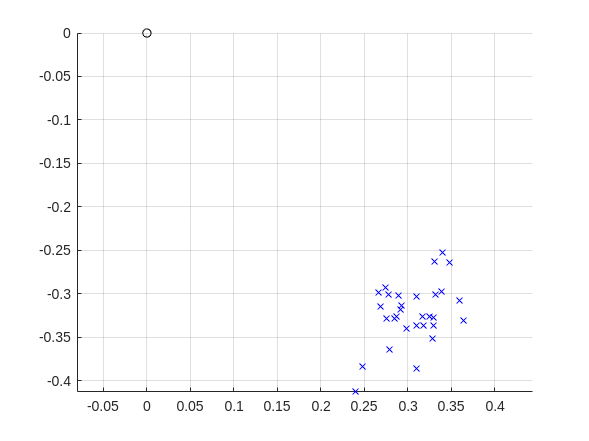

figure()
hold on
plot(endpoints(1, :), endpoints(2, :), 'bx')
plot(0, 0, 'ko')
grid on
axis equal

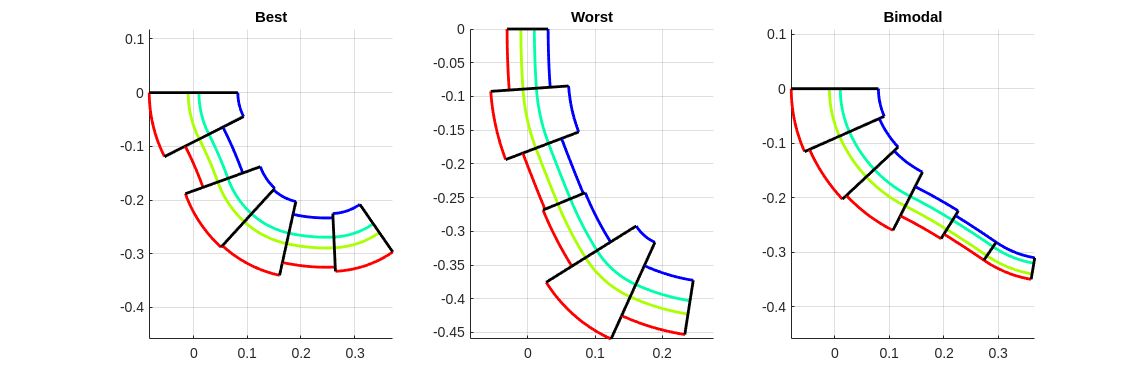

[~, i_best] = max(endpoints(2, :));
[~, i_worst] = min(endpoints(2, :));

fig = figure("Position", [0, 0, 1500, 500]);
ax = subplot(1, 3, 1);
Plotter2D.plot_arm_series(arms(i_best), ax);
title("Best")

ax = subplot(1, 3, 2);
Plotter2D.plot_arm_series(arms(i_worst), ax);
title("Worst")

ax = subplot(1, 3, 3);
Plotter2D.plot_arm_series(arms(end), ax);
title("Bimodal")

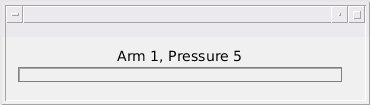

% For each arm, sample M points from its workspace
N_pressures= 20;
p_range = [0, 100];
pressures = rand(arms(1).N_rods, N_pressures) * (p_range(2) - p_range(1)) / 2 + mean(p_range);

Q = [0; -10; 0];

cell_endpoints = cell(N_pressures, N_arms);

f = waitbar(0);
count = 0;
for i_arm = 1 : length(arms)
    arm_i = arms(i_arm);
    for i_pressure = 1 : N_pressures
        p_i = pressures(:, i_pressure);
        arm_i.solve_equilibrium_gina(p_i, Q);
        cell_endpoints{i_pressure, i_arm} = Pose2.vee(arm_i.get_tip_pose());

        count = count + 1;
        waitbar(count / (N_pressures * N_arms), f, sprintf("Arm %i, Pressure %i", i_arm, i_pressure));
    end
end


close(f);

end_poses = [cell_endpoints{:}];
figure()
scatter(end_poses(1, :), end_poses(2, :));
axis equal
grid on

figure()
hold on
for i = 1 : size(cell_endpoints, 1)
    endpoints_p_i = [cell_endpoints{i, :}];
    
    scatter(endpoints_p_i(1, :), endpoints_p_i(2, :));
end
axis equal
grid on